for i =1:16 
    im = im2double(imread("Faces/db1_" + i + ".jpg"));
    for j = 1:5
            im = testa(im);  
    end
    imshow(im);title(i)
    pause(0.1)
end

Unrecognized function or variable 'testa'.

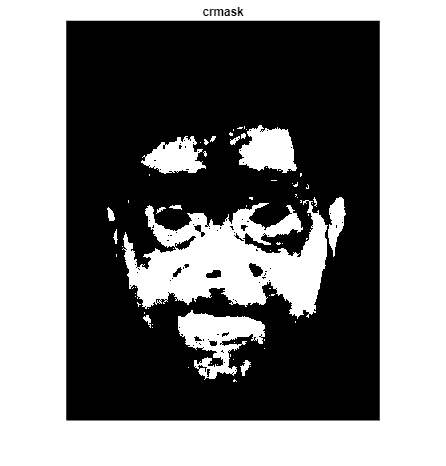

clear all
imIn = im2double(imread("Faces/db1_" + 1 + ".jpg"));
imIn = im2uint8(imIn);
imIn = AWB(imIn, 20);
imIn = colorCorrection(imIn);
imIn = AWB(imIn,0);
imIn = contrastStretchColor(imIn,0,1);
% Convert the RGB image to YCgCr color space
ycgcrImage = rgb2ycgcr(imIn);

% Extract the Y, Cb, and Cr channels
Y = ycgcrImage(:, :, 1);
Cg = histeq(ycgcrImage(:, :, 2));
Cr = histeq(ycgcrImage(:, :, 3));

% Define thresholds for skin color in YCbCr space
% Trail and Error Values
Ymin = 0.5;
Ymax = 0.62;
Cgmin = 0.3;
Cgmax = 0.55;
Crmin = 0.06;
Crmax = 0.85;

crmask = ~(Crmin <= Cr & Cr <= Crmax);
imshow(crmask); title('crmask')


cgmask = (Cgmin <= Cg & Cg <= Cgmax);
imshow(cgmask); title('cgmask')

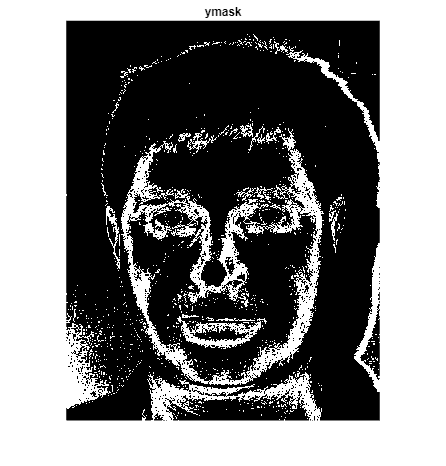


ymask = (Ymin <= Y & Y <= Ymax);
imshow(ymask); title('ymask')

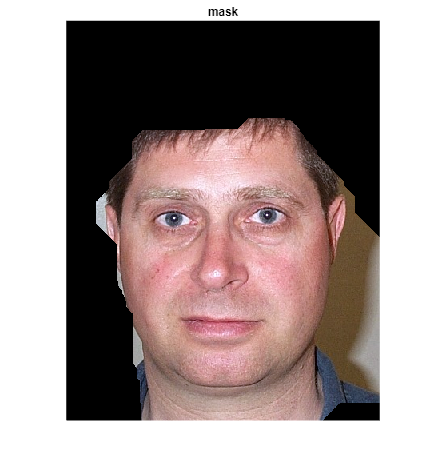


% Create binary masks for skin regions
mask = ymask | cgmask | crmask;

SE = strel('disk', 6);
mask = imerode(mask, SE);
mask = imclose(mask, SE);

SE = strel('disk', 19);% was 8 before 2023-11-22
mask = imdilate(mask, SE);
mask = imclose(mask, SE);

SE = strel('disk', 10);
mask = imclose(mask, SE);

% Filter image, retaining only the 5 objects with the largest areas.
mask = bwareafilt(mask,1);
SE = strel('disk', 350);
mask = imclose(mask, SE);
mask = imfill(mask, 'holes');

test = mask.*imIn;
imshow(mask.*imIn); title('mask')

function ycgcrImage = rgb2ycgcr(rgbImage)
    % Define the conversion matrix for RGB to YCgCr
    conversionMatrix = [0.299 0.587 0.114; -0.1687367 -0.331264 0.5; 0.5 -0.418688 -0.081312];
    
    % Convert the RGB image to YCgCr
    [rows, cols, ~] = size(rgbImage);
    ycgcrImage = zeros(rows, cols, 3);
    
    for i = 1:rows
        for j = 1:cols
            pixel = double(reshape(rgbImage(i, j, :), 3, 1));
            ycgcrPixel = conversionMatrix * pixel;
            ycgcrImage(i, j, :) = ycgcrPixel;
        end
    end

    % Normalize the YCgCr channels
    ycgcrImage(:, :, 2) = ycgcrImage(:, :, 2) + 0.5;
    ycgcrImage = min(max(ycgcrImage, 0), 1);
end

